load('proj6_arterialFlowData_qfi.mat');

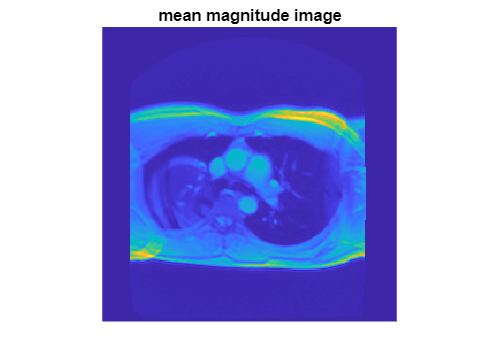

figure
meanAtEachTimeStep = mean(mag_3d,[1 2]);
meanOverTime = mean(mag_3d,3);
imagesc(meanOverTime)
axis image
axis off
title('mean magnitude image')

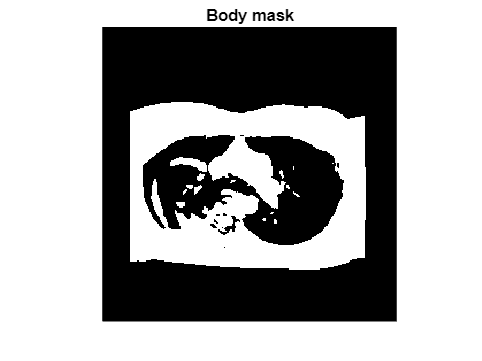

% Create head mask
imageMax = max(mag_3d(:));
bodyMask_m = (meanOverTime > 0.1*imageMax);
figure
imagesc(bodyMask_m)
colormap(gray)
axis image
axis off
title('Body mask')

vz_3d = (venc/(pi/2)).*phase_3d;

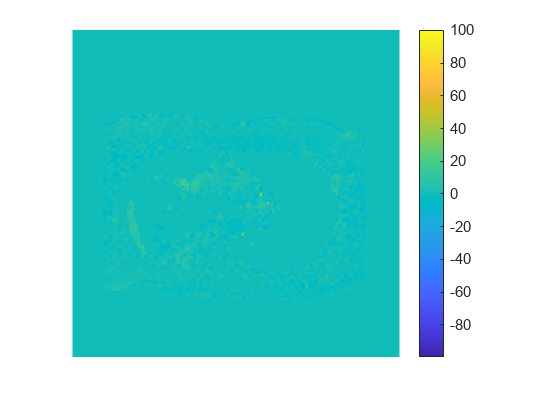

% Show a movie of velocity versus time. Red is flow toward head,
% blue is toward feet:
nTimes = length(time_v);
maxVz = max(vz_3d(:));
minVz = min(vz_3d(:));
figure
for timeIndex = 1:nTimes
    imagesc(bodyMask_m .* vz_3d(:, :, timeIndex))
    colorbar
    axis image
    axis off
    % Set color limits to visualize slow and fast flow:
    set(gca, 'CLim', [minVz, maxVz]/2)
    drawnow
    mov(timeIndex) = getframe;
end

nLoops = 2;
fps = 0.8;    % Frames per second.
movie(mov, nLoops, fps)

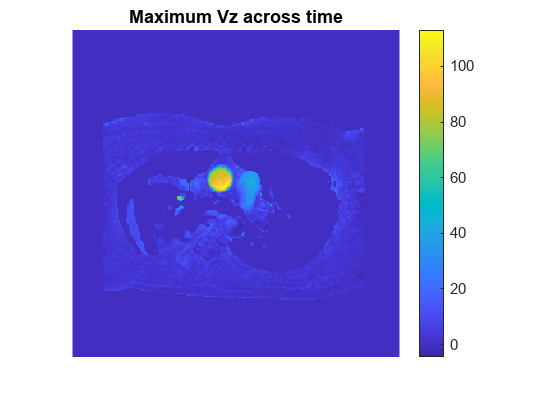

maxVz_m = max(vz_3d, [], 3);
figure;
imagesc(maxVz_m .* bodyMask_m)
axis image
axis off
colorbar
title('Maximum Vz across time')

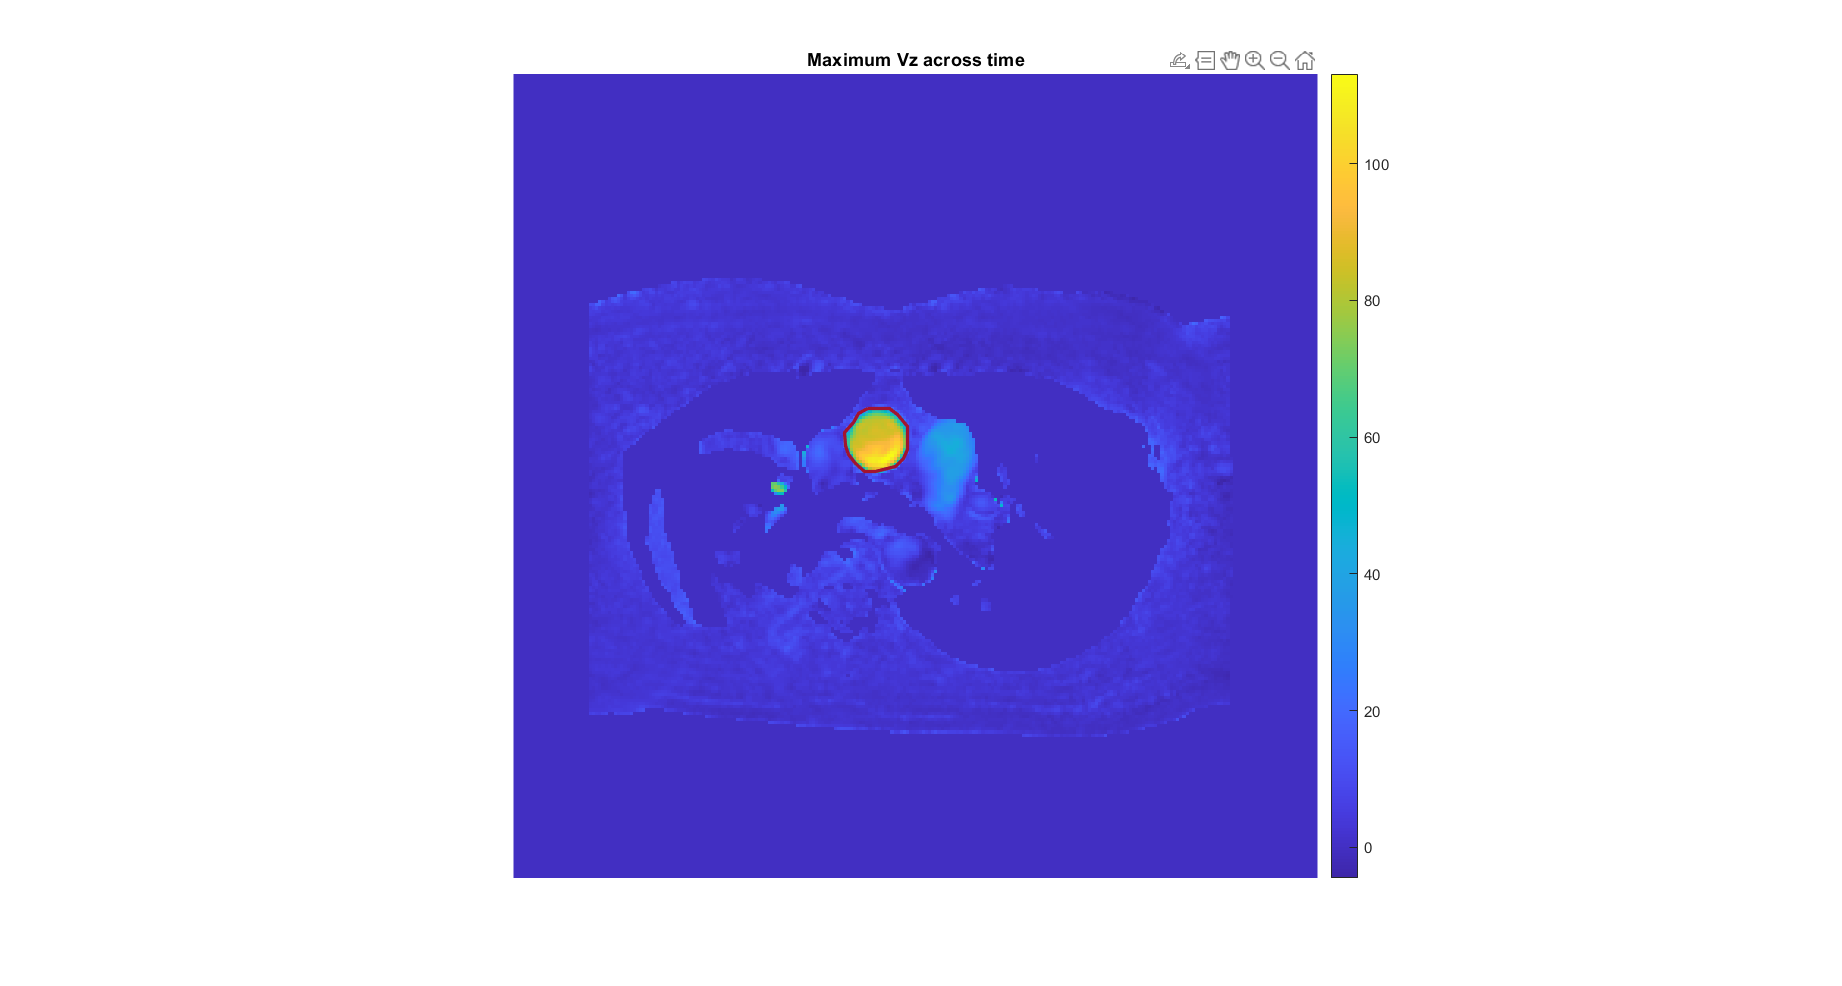

[aaMask_m, aaX_v, aaY_v] = roipoly;
aaMask_m = aaMask_m .* bodyMask_m;
line(aaX_v, aaY_v, 'Color', '#A2142F','LineWidth',2) ;

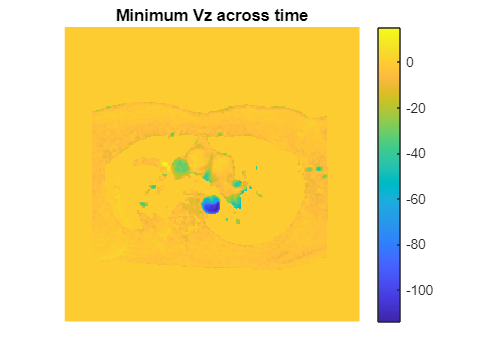

minVz_m = min(vz_3d, [], 3);
figure;
imagesc(minVz_m .* bodyMask_m)
axis image
axis off
colorbar
title('Minimum Vz across time')

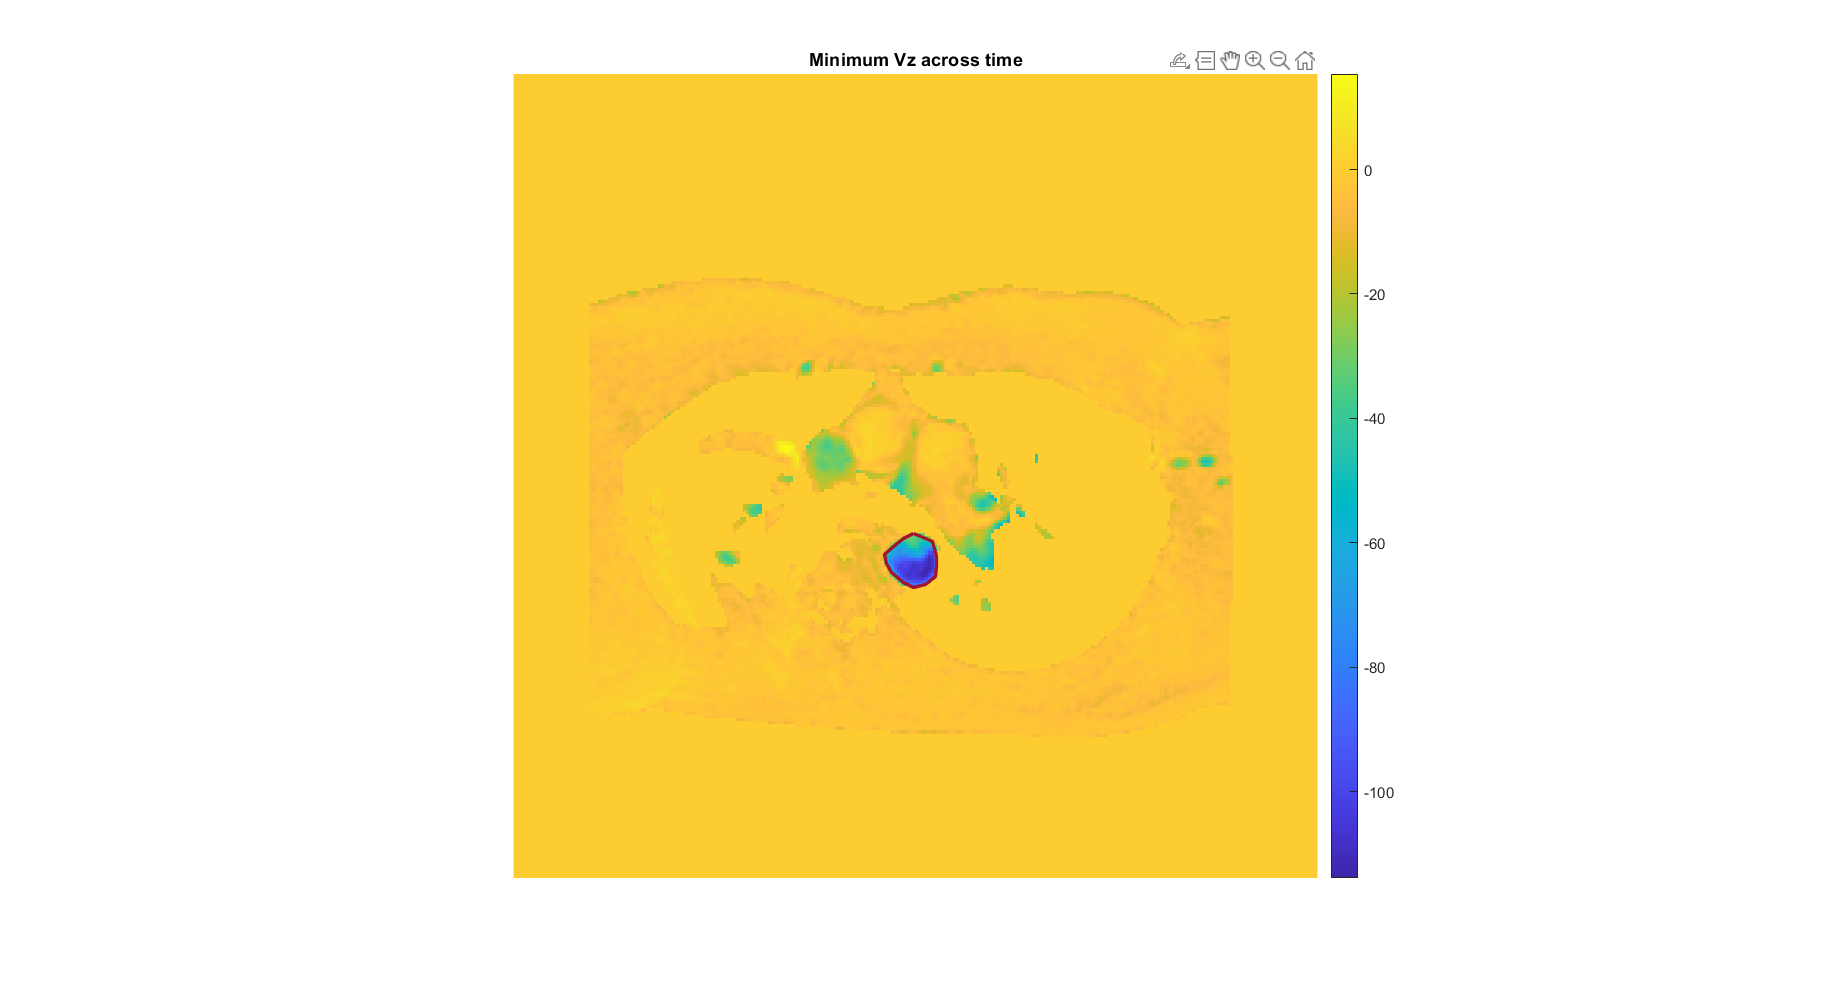

[daMask_m, daX_v, daY_v] = roipoly;
daMask_m = daMask_m .* bodyMask_m;
line(daX_v, daY_v, 'Color', '#A2142F','LineWidth',2);

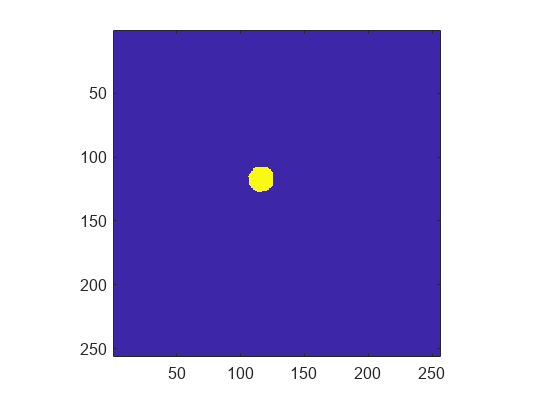

imagesc(aaMask_m)
axis image

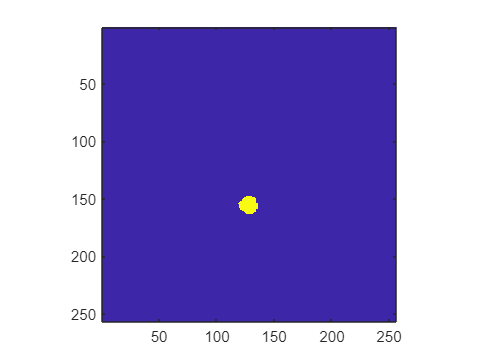

imagesc(daMask_m)
axis image

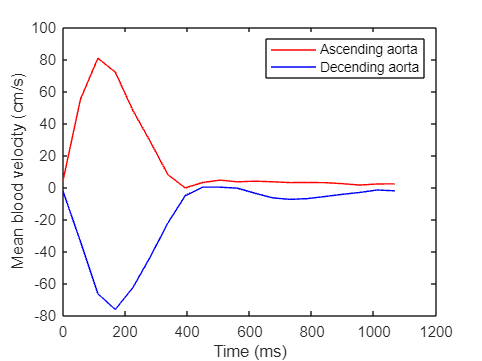

nTimes = length(time_v);
aaVz_v = zeros(1, nTimes);
daVz_v = zeros(1, nTimes);
num_aaVz = sum(sum(aaMask_m));
num_daVz = sum(sum(daMask_m));
for timeIndex = 1:nTimes
    % Insert your code to calculate the mean velocity
    % in each vessel at the current time point:
    % CANT do aaVz_v(timeIndex) = sum(aaMask_m*vz_3d, [], 3);
    
    aaVz_v(timeIndex) = sum(sum(aaMask_m.*vz_3d(:,:,timeIndex)))./num_aaVz;
    daVz_v(timeIndex) = sum(sum(daMask_m.*vz_3d(:,:,timeIndex)))./num_daVz;
end
plot(time_v, aaVz_v, "r", time_v, daVz_v, "b")
ylabel('Mean blood velocity (cm/s)')
xlabel('Time (ms)')
legend('Ascending aorta', 'Decending aorta')

save('masksAAandDA.mat','aaMask_m','daMask_m', 'bodyMask_m');
save('ROIsFlow.mat',"aaVz_v","daVz_v");

load('masksAAandDA.mat');
load('proj6_arterialFlowData_qfi.mat');
load('ROIsFlow.mat');
num_aaVz = sum(sum(aaMask_m));
num_daVz = sum(sum(daMask_m));

aaArea = num_aaVz * dx * dy* 10^(-6); 
daArea = num_daVz * dx * dy* 10^(-6); 
aaVol = aaArea * trapz(10^(-3).*time_v, 10^(-2).*aaVz_v) * 10^6

aaVol = 107.7249

daVol = abs(daArea * trapz(10^(-3).*time_v, 10^(-2).*daVz_v)) * 10^6

daVol = 75.1641

fracDiff = 30.2259

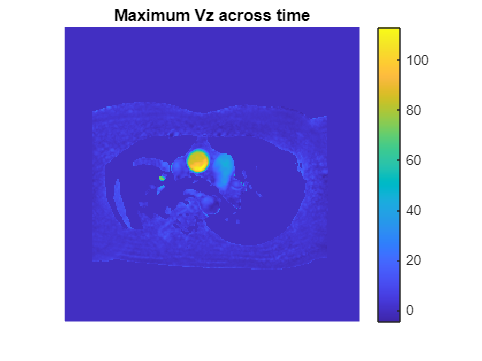

fracDiff = 100 * (aaVol - daVol) / aaVol 

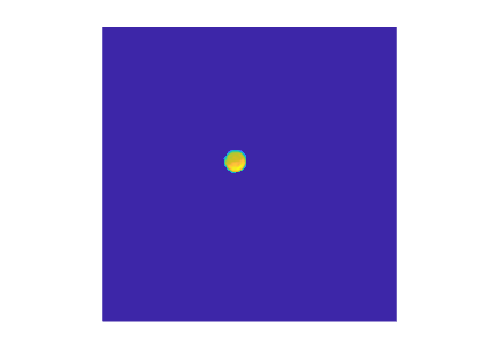

[maxVal, maxIndx] = max(aaVz_v);
timeOfMax = time_v(maxIndx);
maxaaV_m = aaMask_m.*vz_3d(:,:,maxIndx);
imagesc(maxaaV_m)
axis image
axis off

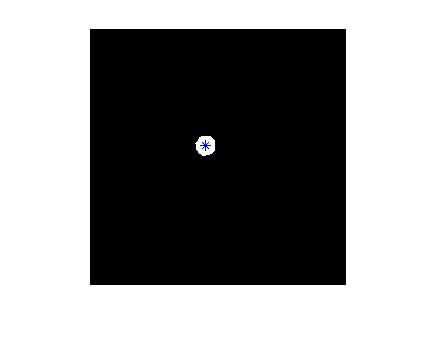

s  = regionprops(aaMask_m, 'centroid');
centroids = cat(1, s.Centroid);
ax = centroids(:,1);
ay = centroids(:,2);
imshow(aaMask_m)
hold on
plot(ax, ay, 'b*')
hold off

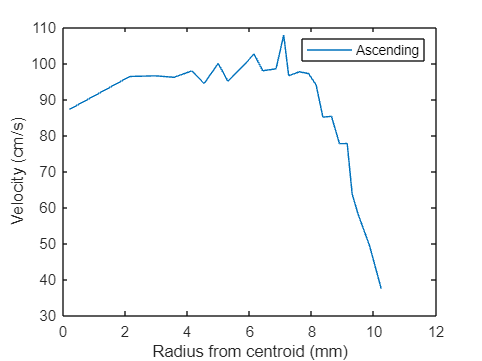

[y_cord, x_cord] = find(aaMask_m);
radius = pdist2(centroids, [x_cord, y_cord]);
allParams = [radius', x_cord, y_cord];
allParams = sortrows(allParams); 
% initialize
[minRadius, indexMinRad] = min(radius);
meanRadius = minRadius;
meanVelocity = maxaaV_m(y_cord(indexMinRad), x_cord(indexMinRad));
binNum = 13;
for index = 1 : length(allParams)
    velocityByRadius(index) = maxaaV_m(allParams(index,3), allParams(index,2));
    if mod(index,binNum)==1 && index > 1
        meanVelocity(end+1) = sum(velocityByRadius(index-binNum:index))/binNum; 
        meanRadius(end+1) = allParams(index,1);
    end 
end 

figure
plot(meanRadius, meanVelocity)
xlabel("Radius from centroid (mm)")
ylabel("Velocity (cm/s)")
legend('Ascending')